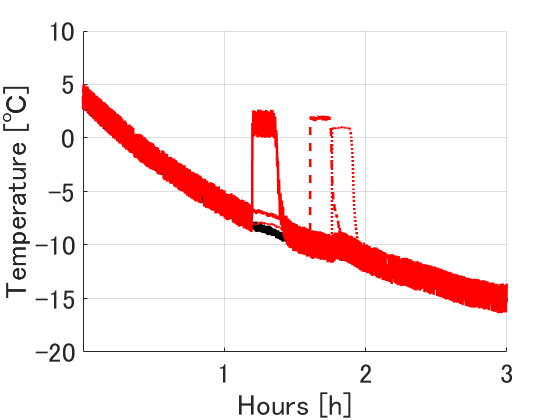

clearvars
load("magnetites_sample.mat");
time_setting=[5,6];
output=table2array(a211020_3magnetites_2A_10Hz(:,3:6));

start=find(output(500:12283,2)<5, 1 )+500;
finish=3600*time_setting(2)/time_setting(1)+start;
time=(0:time_setting(1):size(output)*time_setting(1)-1).'/3600;
time=time-time(start);

output2=output(start:start+3*60*60/5-1,:);
time2=time(start:start+3*60*60/5-1,:);
fig1=figure;
hold on
plot(time2,output2(:,1),'k-',"LineWidth",2)
plot(time2,output2(:,2),'r-',"LineWidth",2)
plot(time2,output2(:,3),'r--',"LineWidth",2)
plot(time2,output2(:,4),'r:',"LineWidth",2)
xlabel('Hours [h]');
ylabel('Temperature [℃]');
xticks([1,2,3,4,5,6]);
xticklabels({'1','2','3','4','5','6'});
grid on
ylim([-20 10]);
hold off;
set(gca,"fontSize",20)

Y=fft(output2(1:3*60*60/5,:));
P2=abs(Y/2160);
P1=P2(1:2160/2+1,:);
P1(2:end-1,:)=2*P1(2:end-1,:);

f=0.2*(0:(2160/2))/2160;

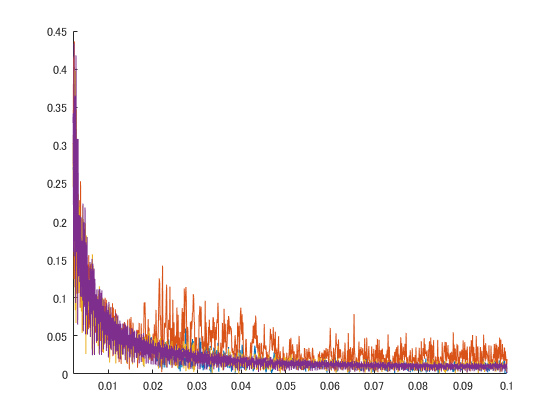

fig2=figure;
hold on
plot(f,P1);
xlim([0.002 .1]);

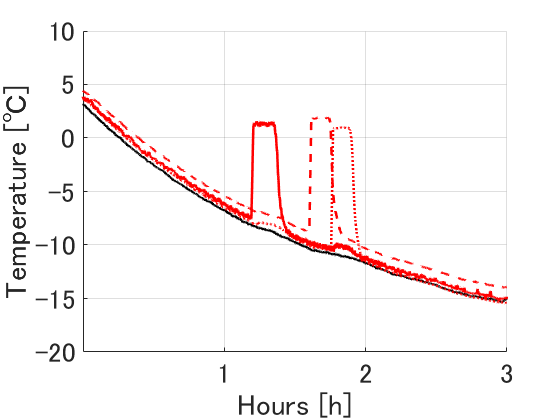

output3=movmean(output2,10);

fig3=figure;
hold on
plot(time2,output3(:,1),'k-',"LineWidth",2)
plot(time2,output3(:,2),'r-',"LineWidth",2)
plot(time2,output3(:,3),'r--',"LineWidth",2)
plot(time2,output3(:,4),'r:',"LineWidth",2)
xlabel('Hours [h]');
ylabel('Temperature [℃]');
xticks([1,2,3,4,5,6]);
xticklabels({'1','2','3','4','5','6'});
grid on
ylim([-20 10]);
hold off;
set(gca,"fontSize",20)